# 光学观测定轨

## 1.题目

已知某测站的位置为：经度24.583º，纬度5.866º，高程0m。对某一地球卫星进行观测，得到的高低角、方位角以及距离的数据如下表所示。观测时，高低角、方位角及距离均带有噪声。地球赤道半径为6378.140km，偏心率ee = 0.081 819。

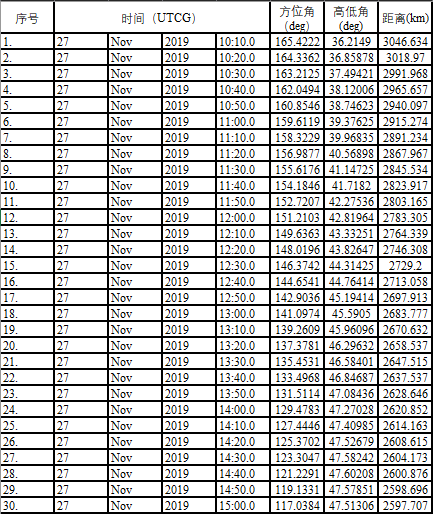

1.1 试仅利用角度观测数据，采用拉普拉斯方法和高斯方法确定卫星的轨道根数，并分析结果间的差异。

1.2 试采用距离观测数据，改进卫星轨道确定的精度。

## 2.求解

### 2.1 数据导入

clear;
lambda = 24.583; %longitude，经度
latitude = 5.866;
altitude = 0;
data = xlsread('data.xlsx');
azimuth = data(:,5);
elevation = data(:,6);
distance = data(:,7)*1000; %注意单位转换

由于读入的小时-分钟-秒数据被自动转为小数，以及月份读到的是NaN，因此需要做一步处理。

UTC=datetime(2019,11,27,floor(data(:,4)*24),floor(data(:,4)*24*60)-floor(data(:,4)*24)*60,floor(data(:,4)*24*3600-floor(data(:,4)*24)*3600-(floor(data(:,4)*24*60)-floor(data(:,4)*24)*60)*60));

### 2.2 求当地真恒星时

timesystem = timeSystem.TimeSystem(UTC,lambda)

timesystem =   TimeSystem with properties:

        UTC: [30×1 datetime]
    lambdaG: 24.5830
     lambda: 24.5830
        TAI: [30×1 datetime]
         TT: [30×1 datetime]
        TDT: [30×1 datetime]
         ET: [30×1 datetime]
        UT1: [30×1 datetime]
      Smean: [30×1 double]
          S: [30×1 double]
      smean: [30×1 double]
          s: [30×1 double]


### 2.3 观测数据预处理

观测数据预处理，由于该Preprocessing需要输入变化率，因此置变化率为零

Dazimuth = zeros(length(data(:,1)),1);
Delevation = zeros(length(data(:,1)),1);
Ddistance = zeros(length(data(:,1)),1);
preprocessing = orbitDefine.Preprocessing(latitude,timesystem.s/3600*15,altitude,azimuth,elevation,distance,Dazimuth,Delevation,Ddistance)

preprocessing =   Preprocessing with properties:

        Glatitude: 5.8660
                s: [30×1 double]
         altitude: 0
          azimuth: [30×1 double]
        elevation: [30×1 double]
         distance: [30×1 double]
         Dazimuth: [30×1 double]
       Delevation: [30×1 double]
        Ddistance: [30×1 double]
       stationPos: [30×3 double]
    spacecraftDir: [30×3 double]
    spacecraftPos: [30×3 double]
    spacecraftVel: [30×3 double]


### 2.4 使用LaplaceMethod求解1.1

### 2.5 使用GaussianMethod求解1.1

### 2.6 使用usingMultiPos求解1.2

orbit=orbitDefine.usingMultiPos(preprocessing.spacecraftPos,UTC)

orbit =   usingMultiPos with properties:

        a: 8.2099e+06
        e: 0.0491
    Omega: 60.2193
    omega: 134.1086
        i: 54.9040
      tao: 2019-11-27 19:56:00
       f0: 213.2022
       E0: 214.7746
       M0: 216.3779
        p: 8.1901e+06
